# Simulations pour la microscopie à 1 photon

## Amplitude dans la pupille de sortie (sans puis avec aberrations)

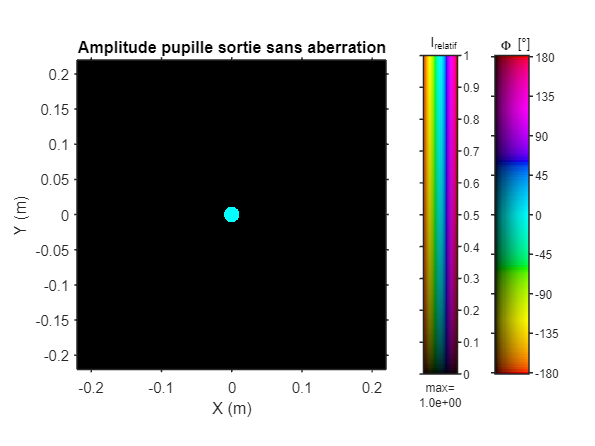

lambda=825e-9; %m
N=2^10;
R_mir=11e-3; %m
k=2*pi/lambda; %m^(-1)
f=15.7889e-3; %m

%échantillon type A oil
n=1.51;
NA=1.04;

zeropadding_factor=20;
x=zeropadding_factor*2*R_mir/N*(-N/2:N/2-1);
y=x;
[X,Y]=meshgrid(x,y);
PDisq=double(X.^2+Y.^2<R_mir^2);
x_norm=x/R_mir;
y_norm=x_norm;
[X_norm,Y_norm]=meshgrid(x_norm,y_norm);
delta=-0.001*lambda*ZnmXY(X_norm,Y_norm,2,0)+0.014*lambda*ZnmXY(X_norm,Y_norm,4,2)+0.03*lambda*ZnmXY(X_norm,Y_norm,4,0); %m

P0=PDisq;

figure
VisuIlinPh(x,y,P0)
title('Amplitude pupille sortie sans aberration')
xlabel('X (m)')
ylabel('Y (m)')

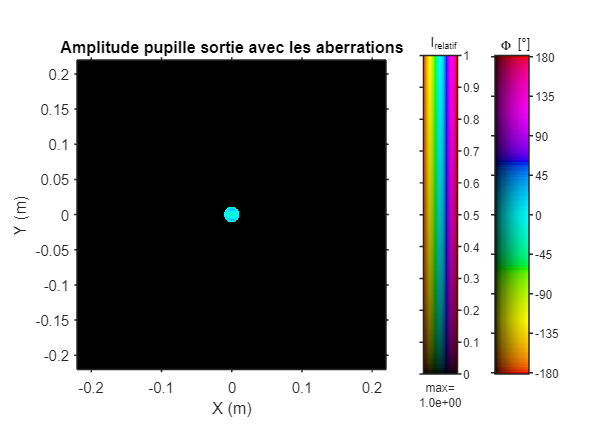

% xlim([-20e-3 20e-3])
% ylim([-20e-3 20e-3])

P=PDisq.*exp(-2i*pi/lambda*n*delta);

figure
VisuIlinPh(x,y,P)
title('Amplitude pupille sortie avec les aberrations')
xlabel('X (m)')
ylabel('Y (m)')

% xlim([-20e-3 20e-3])
% ylim([-20e-3 20e-3])

## Tracé des RPI^2 (2 photons)

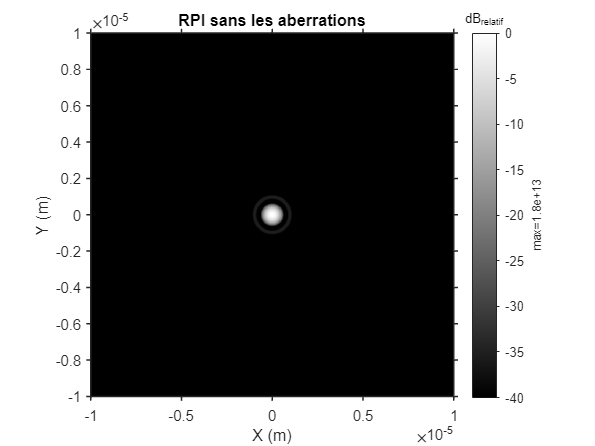

xp=lambda*f/(zeropadding_factor*2*R_mir)*(-N/2:N/2-1);
yp=xp;

RPc0=fftshift(fft2(ifftshift(P0)));
RPI0=abs(RPc0).^2;

figure
VisuIdB(xp,yp,RPI0,-40)
title('RPI sans les aberrations')
xlabel('X (m)')
ylabel('Y (m)')
xlim([-1e-5 1e-5])
ylim([-1e-5 1e-5])

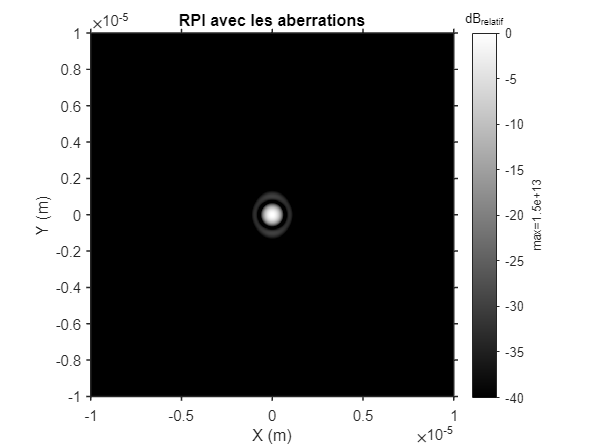


RPc=fftshift(fft2(ifftshift(P)));
RPI=abs(RPc).^2;

figure
VisuIdB(xp,yp,RPI,-40)
title('RPI avec les aberrations')
xlabel('X (m)')
ylabel('Y (m)')
xlim([-1e-5 1e-5])
ylim([-1e-5 1e-5])

## Profil de l'intensité dans le plan YZ (Z direction de propagation) au voisinage du foyer - sans aberration

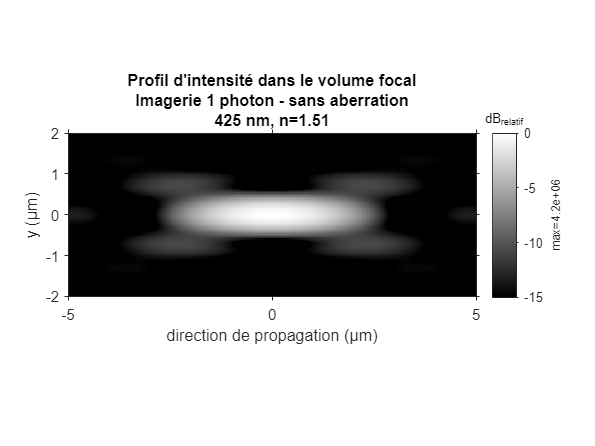

% Calcul de l'amplitude pour plusieurs distances "d" - Sans aberration

FTOc0=fftshift(fft2(ifftshift(RPc0)));

X0_0=zeros(N,N);
compteur=1;
xp=lambda*f/(zeropadding_factor*2*R_mir)*(-N/2:+N/2-1);
yp=xp;
nu_xp=(zeropadding_factor*2*R_mir)/(N*lambda*f)*(-N/2:+N/2-1);
nu_yp=nu_xp;

for zp = linspace(-1e-5,1e-5,N);
    [NU_XP,NU_YP,ZP]=meshgrid(nu_xp,nu_yp,zp);
    Hd_0=exp(-1j*k*zp).*exp(1j*pi*lambda*zp.*(NU_XP.^2+NU_YP.^2)); %définition espace libre
    U0=RPc0;
    U_freq0=FTOc0;
    Udfreq0=U_freq0.*Hd_0;
    U_d0=fftshift(ifft2(fftshift(Udfreq0)));    
    X0_0(:,compteur)=U_d0(:,N/2);
    compteur=compteur+1;
end

%Affichage de l'amplitude pour X= N/2
figure
zp = linspace(-1e-5,1e-5,N);
zpconverti=zp*10^6; %microns
ypconverti=yp*10^6; %microns
VisuIdB(zpconverti,ypconverti,X0_0,-15)
title({"Profil d'intensité dans le volume focal";"Imagerie 1 photon - sans aberration";'425 nm, n=1.51'})
xlim([-5 5]) %microns
ylim([-2 2]) %microns
xlabel('direction de propagation (μm)')
ylabel('y (μm)')

## Profil de l'intensité dans le plan YZ (Z direction de propagation) au voisinage du foyer - avec les aberrations du système

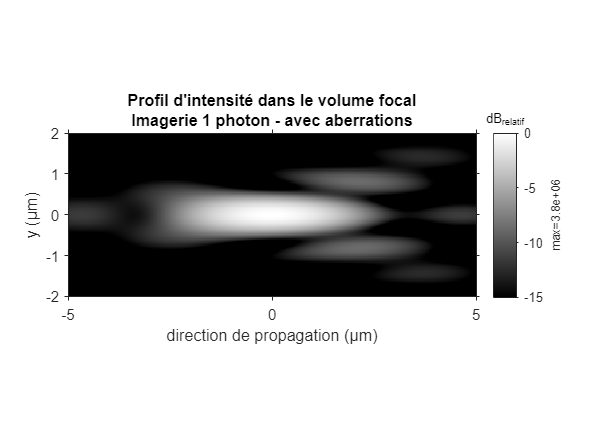

% Calcul de l'amplitude pour plusieurs distances "d" - Avec aberrations

FTOc=fftshift(fft2(ifftshift(RPc)));

X0=zeros(N,N);
compteur=1;
xp=lambda*f/(zeropadding_factor*2*R_mir)*(-N/2:+N/2-1);
yp=xp;
nu_xp=(zeropadding_factor*2*R_mir)/(N*lambda*f)*(-N/2:+N/2-1);
nu_yp=nu_xp;

for zp = linspace(-1e-5,1e-5,N);
    [NU_XP,NU_YP,ZP]=meshgrid(nu_xp,nu_yp,zp);
    Hd=exp(-1j*k*zp).*exp(1j*pi*lambda*zp.*(NU_XP.^2+NU_YP.^2)); %définition espace libre
    U=RPc;
    U_freq=FTOc;
    Udfreq=U_freq.*Hd;
    U_d=fftshift(ifft2(fftshift(Udfreq)));    
    X0(:,compteur)=U_d(:,N/2);
    compteur=compteur+1;
end

%Affichage de l'amplitude pour X= N/2
figure
zp = linspace(-1e-5,1e-5,N);
zpconverti=zp*10^6; %microns
ypconverti=yp*10^6; %microns
VisuIdB(zpconverti,ypconverti,X0,-15)
title({"Profil d'intensité dans le volume focal";"Imagerie 1 photon - avec aberrations";'425 nm, n=1.51'})
xlim([-5 5]) %microns
ylim([-2 2]) %microns
xlabel('direction de propagation (μm)')
ylabel('y (μm)')